# **ACM 11 Homework 5 Part 2: Classification**

## Introduction

Do Part 1 first. Then do this part.

## Problem 1: Classification via logistic regression

**(1a) **Please load the ''Auto.csv" data set into MATLAB as you did in Part 1. In this case, we will consider the first 8 variables (i.e., columns) in the dataset.

clear; close all
data = readtable('Auto.csv')

data = 392×9 table
    mpg    cylinders    displacement    horsepower    weight    acceleration    year    origin                name             
    ___    _________    ____________    __________    ______    ____________    ____    ______    _____________________________

    18         8            307            130         3504           12         70       1       {'chevrolet chevelle malibu'}
    15         8            350            165         3693         11.5         70       1       {'buick skylark 320'        }
    18         8            318            150         3436           11         70       1       {'plymouth satellite'       }
    16         8            304   

**(1b) **In this part of the problem, we are interested not in the exactly MPG value for each car, but in whether the car has a higher-than-median MPG. 

(i) Create a binary variable $y$ that is 1 if MPG for a given car is above the median, and 0 if it is below the median MPG value. If it is exactly the median, you can choose whether it is 1 or 0.

mpg_matrix = table2array(data(:,1));
y = zeros(1, length(mpg_matrix));
median = median(mpg_matrix);

for i = 1:length(y)
    if (mpg_matrix(i) > median)
        y(i) = 1;
    else
        y(i) = 0;
    end
end

(ii) We will use the 7 remaining variables in the data set (cylinders, displacement, horsepower, weight, acceleration, year and origin) to predict whether a car has above or below median MPG. Assemble the 7 remaining variables into a data matrix $X$ where each column contains one variable.

X = table2array(data(1:end, 2:8));

(iii) Use the function `GSCATTER` to create a scatter plot of weight vs. horsepower, grouped according to $y$. Include appropriate axes labels and a legend.

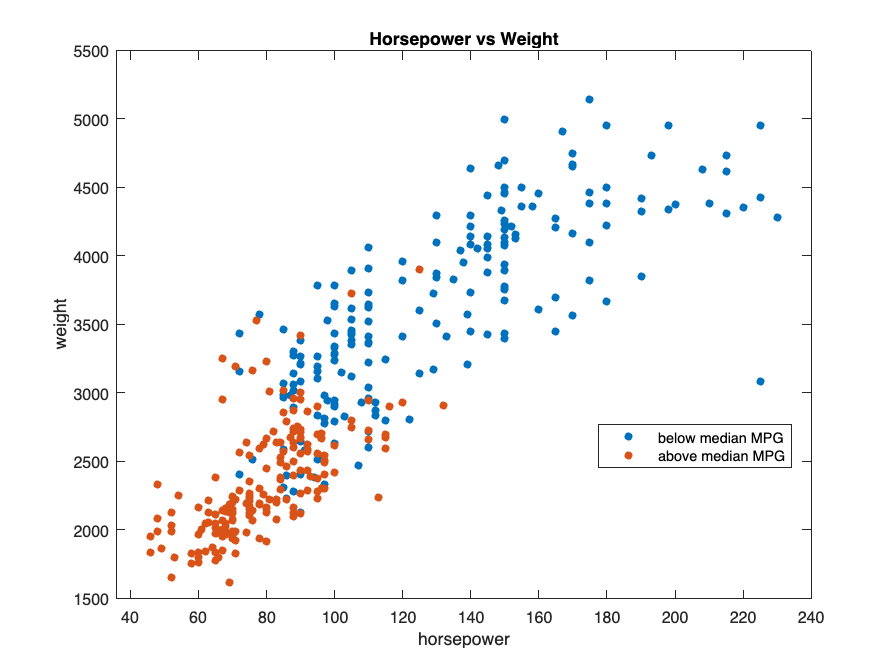

weight = X(:,4);
hp = X(:,3);

figure(1); clf
gscatter(hp, weight, y);
title("Horsepower vs Weight");
xlabel("horsepower");
ylabel("weight");
legend("below median MPG", "above median MPG");

**(1c) **Split your data into a training and test set. For $n_{\textrm{train}} =300$, use the first $n_{\textrm{train}}$ entries of $y$ and rows of $X$ for training, and save the remaining entries/rows for testing the fitted model. 

n_train = 300;

train_x = X(1:n_train,:);
train_y = y(1:n_train);
test_x = X((n_train + 1):end,:);
test_y = y((n_train + 1):end);

**(1d) **Call the built-in `MNRFIT` function on your training inputs and outputs to fit a classifier. This is a model that will predict the output label for a new input x. Note that the second argument of `MNRFIT` must be a categorical variable. You can convert $y$ into a categorical variable using `categorical(y)`.

class = mnrfit(train_x, categorical(train_y));

**(1e) **Use the built-in function MNRVAL to evaluate your classifier on both the training and test sets. MNRVAL will return two values in each row; they are the probabilities that the car with the properties in that row has $y=0$ or $y=1$, respectively. You should set your prediction to be 0 if the first probability is higher than the second, and your prediction to be 1 otherwise. Hint: the syntax `(x>y)` where x and y are vectors of the same shape will return a third vector of the same shape with 1's where x>y and 0's otherwise.

eval_train = mnrval(class, train_x);
eval_test = mnrval(class, test_x);
predict_train = (eval_train(:, 1) < eval_train(:, 2));
predict_test = (eval_test(:, 1) < eval_test(:, 2));

**(1f) **Use `GSCATTER` to plot (i) the training data set horsepower & weight gro;uped according to whether the classifier prediction is correct or not, and (ii) the same for the test set. Hint: the syntax `x==y` for vectors x and y of the same shape returns a 1 when x = y and a 0 otherwise. Include appropriate axes labels, legends, and title.

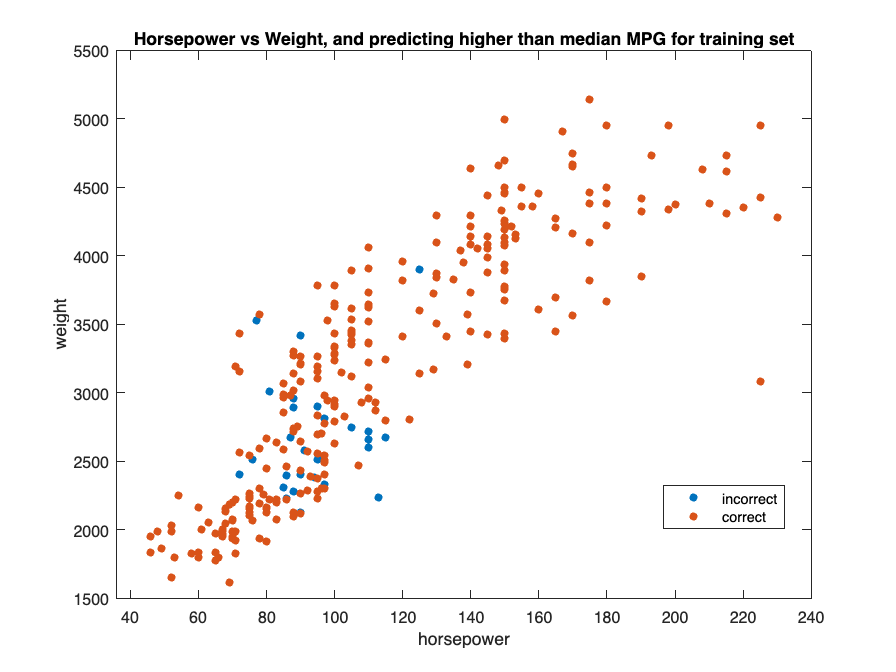

correctness_train = (train_y.' == predict_train);
correctness_test = (test_y.' == predict_test);

figure(2); clf
gscatter(hp(1:n_train), weight(1:n_train), correctness_train);
title("Horsepower vs Weight, and predicting higher than median MPG for training set");
xlabel("horsepower");
ylabel("weight");
legend("incorrect", "correct");

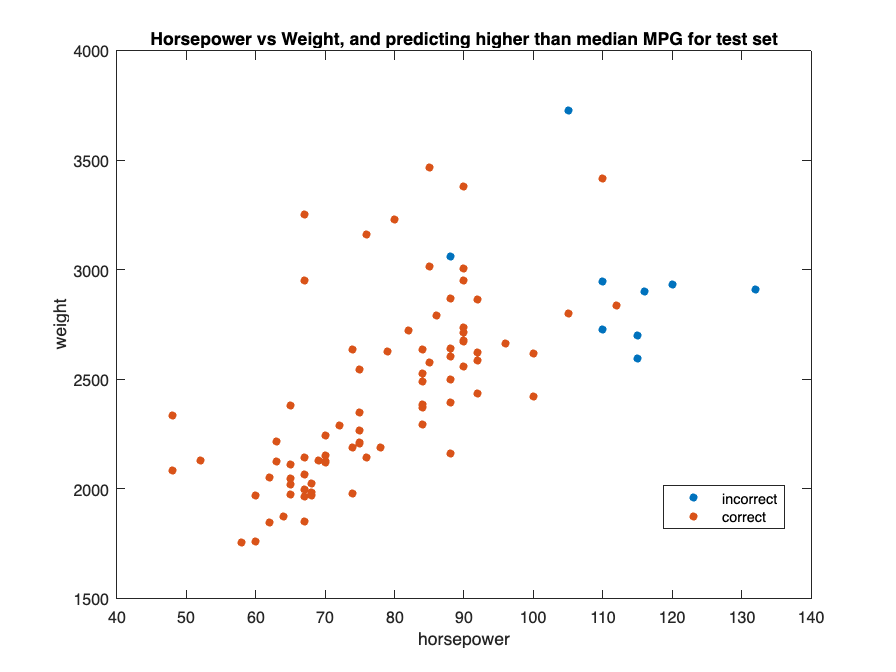


figure(3); clf
gscatter(hp((n_train + 1):end), weight((n_train + 1):end), correctness_test);
title("Horsepower vs Weight, and predicting higher than median MPG for test set");
xlabel("horsepower");
ylabel("weight");
legend("incorrect", "correct");

**(1g) **What is the misclassification rate for the training set? For the test set? Misclassification rate = # of misclassified cars divided by total number of cars in the set. Please comment below where the misclassified points lie among the data for both the training and test set.

train_misclass_rate = sum(correctness_train == 0) / length(correctness_train)

train_misclass_rate = 0.0967

fprintf("The misclassification rate for the training set is %d", train_misclass_rate)

The misclassification rate for the training set is 9.666667e-02



test_misclass_rate = sum(correctness_test == 0) / length(correctness_test)

test_misclass_rate = 0.0978

fprintf("The misclassification rate for the test set is %d", test_misclass_rate)

The misclassification rate for the test set is 9.782609e-02


%shows in scientific notation

*For the training set the misclassified points are in the center of the distribution and for the test set they are on the higher side of the horsepower. For both sets the misclassifications tend to occur around 80-120 horsepower (all occur within 70-130 hp).*

## **Problem 2: Classification via K-Nearest Neighbors**

Now, using the same training/test split as above, use the built-in funcion `FITCKNN` to fit a k-Nearest Neighbor (kNN) classifier. Specify the number of neighbors $k$ when fitting your kNN model, and try $k=1,\ldots, 50$. Check the document for `FITCKNN` to see how to specify this parameter. Train your model on the train set and test it your the test set using the `PREDICT` function. Compute the misclassification rate for both training and test sets. On the same axis, plot the misclassification rate for training and test sets vs $k$. 

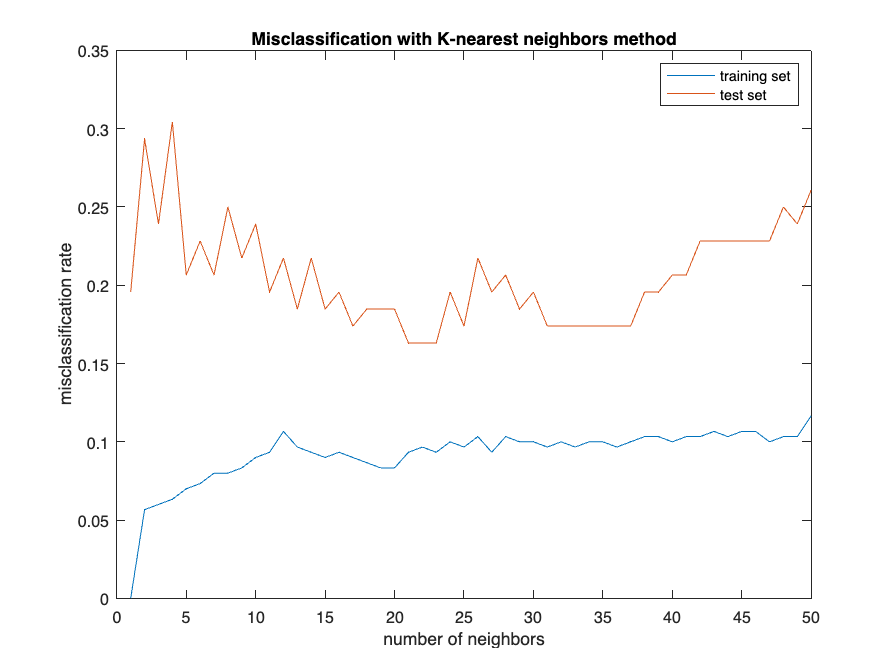

k = (1:50);

train_misclass_rate = zeros(1, length(k));
test_misclass_rate = zeros(1, length(k));
for i = k
    % training
    knn = fitcknn(train_x, train_y, 'NumNeighbors', k(i));
    predict_train = predict(knn, train_x);
    match_train = (train_y.' == predict_train);
    train_misclass_rate(i) = sum(match_train == 0) / length(match_train);

    %test set
    predict_test = predict(knn, test_x);
    match_test = (test_y.' == predict_test);
    test_misclass_rate(i) = sum(match_test == 0) / length(match_test);
end


figure(4); clf
plot(k, train_misclass_rate);
hold on
plot(k, test_misclass_rate);
title("Misclassification with K-nearest neighbors method")
xlabel("number of neighbors");
ylabel("misclassification rate");
legend("training set", "test set");

Describe the general trends you observe in the training and test misclassification rates as the number of neighbors used to classify increases. For test error, especially, look for the overall large shape of the error function; there will be many small ups and downs that you should "smooth out" in your head. 

*For the training set, there appears to be a logarithmic type of graph where the misclassification rate increases quickly when k is small then as k increases the missclassification rate's rate of growth decreases. The test set appears to be like a quadratic (with a weak rate of change throughout). *

How many neighbors leads to the lowest training error? The lowest test error? Explain why these are different.

*The lowest training error occurs with 1 neighbor and the lowest test error is around 22-23 neighbors. These are different because for the training set as the number of neighbors increases the classifier is more likely to select more points with a different classification, leading to a less accurate model for the training set. The test set benefits from a larger amount of neighbors because it's data is very different from that of the training set, so more variety helps, but if too many neighbors are considered, again we begin to leak to many neighbors who are a different classification then the point we are attempting to classify (leading to the more misclassification).*